# Laboratorium 5

Janusz Pawlicki

## 1. Wstęp

### Równania opisujące zawieszenie samochodu

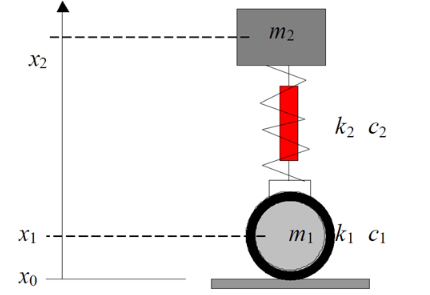

x0 - współrzędna pionowa podłoża

x1 - współrzędna pionowa środka masy koła

x2 - wpsółrzędna pionowa środka masy nadwozia

Odchyłkowe zmienne:

Po podstawieniu i przekształceniach:

Po uproszeczeniu:

## 2. Przebieg laboratorium 

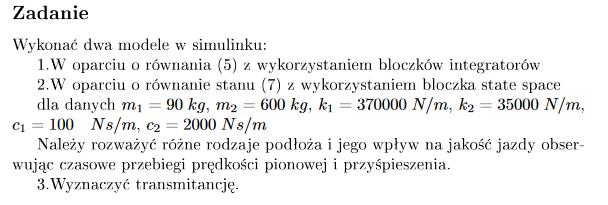

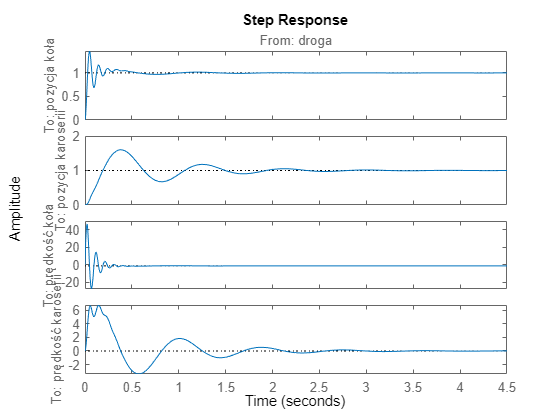

clear

m1 = 90;
m2 = 600;
k1 = 370000;
k2 = 35000;
c1 = 100;
c2 = 2000;

A = [0 0 1 0; 0 0 0 1; -(k1 + k2)/m1 k2/m1 -(c1 + c2)/m1 c2/m1; k2/m2 -k2/m2 c2/m2 -c2/m2];
B = [(c1/m1); 0; (k1/m1) - ((c1 + c2)*c1)/(m1*m1); (c1*c2)/(m1*m2)];
C = eye(4,4);
D = [0; 0; 0; 0];

sys = ss(A,B,C,D, ...
    'InputName','droga',...
    'StateName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'}, ...
    'OutputName',{'pozycja koła', 'pozycja karoserii', 'prędkość koła', 'prędkość karoserii'});

%Wykres odpowiedzi skokowej
step(sys)

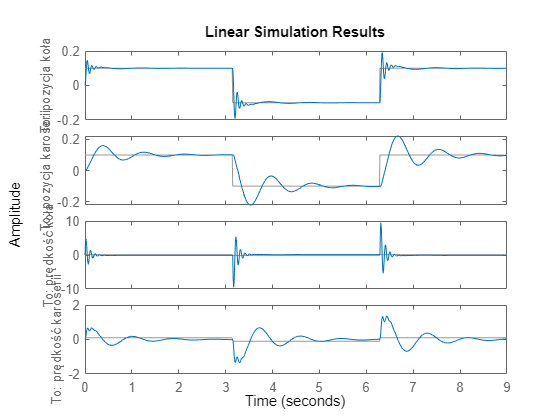

%Symulacja liniowa sygnału
figure
t = 0:0.01:9;
u = 0.1 * square(t);
lsim(sys,u,t)

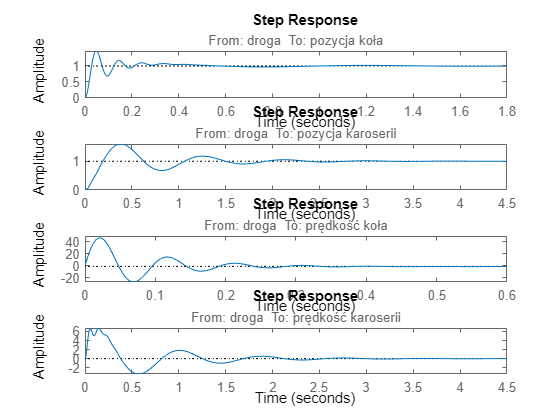


%Obliczenie transmitancji

[licz, mian] = ss2tf(A,B,C,D,1);

G1 = tf(licz(1,:),mian,'InputName','droga','OutputName','pozycja koła');
G2 = tf(licz(2,:),mian,'InputName','droga','OutputName','pozycja karoserii');
G3 = tf(licz(3,:),mian,'InputName','droga','OutputName','prędkość koła');
G4 = tf(licz(4,:),mian,'InputName','droga','OutputName','prędkość karoserii');

figure

subplot(4,1,1)
step(G1)
subplot(4,1,2)
step(G2)
subplot(4,1,3)
step(G3)
subplot(4,1,4)
step(G4)

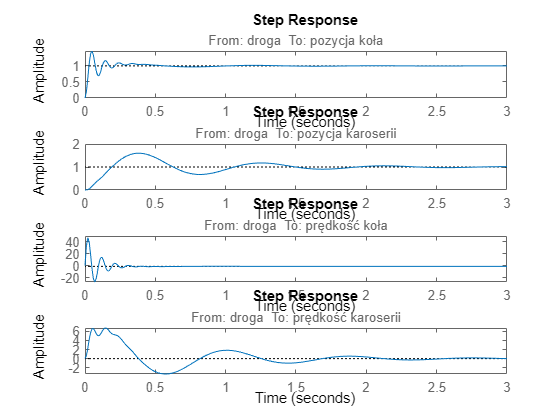


figure

t1 = 0:0.01:3;
subplot(4,1,1)
step(G1,t1)
subplot(4,1,2)
step(G2,t1)
subplot(4,1,3)
step(G3,t1)
subplot(4,1,4)
step(G4,t1)

### 2.1 Simulink

%Model w Simulinku oraz wykresy
zawieszenie_samochodu

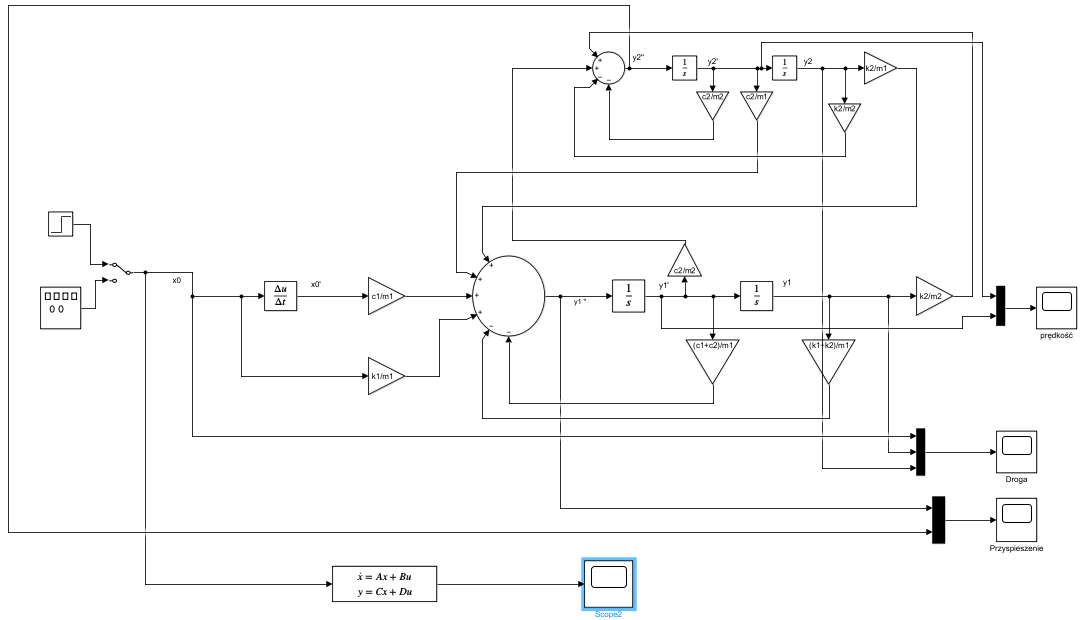

### Wykres drogi

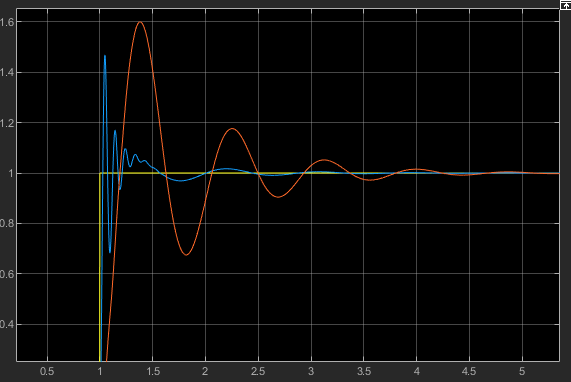

### Wykres prędkości

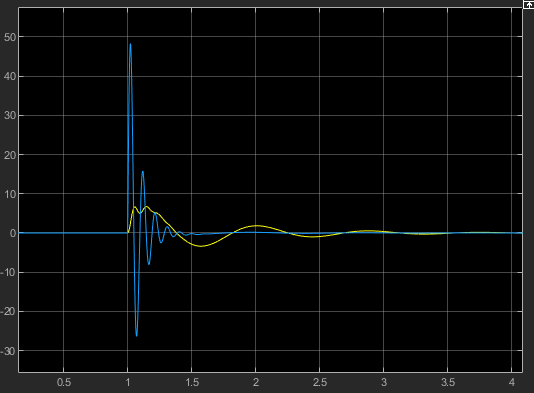

### Wykres przyspieszenia

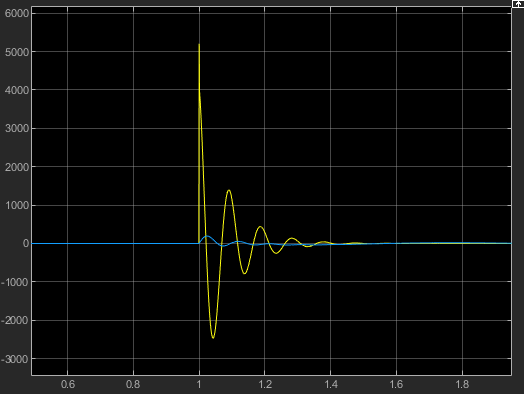

### Wykres z bloku state_space

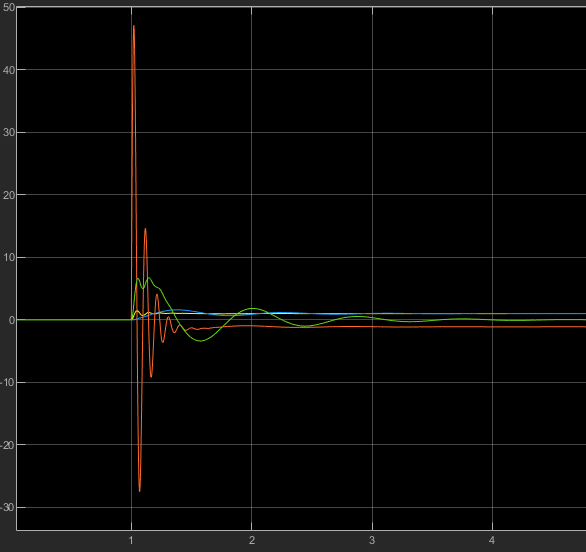

## 3. Bibliografia

https://upel.agh.edu.pl/pluginfile.php/61762/mod_resource/content/2/Zawieszenie.pdf